# Run Your Function

Calling with two outputs

This works correctly.

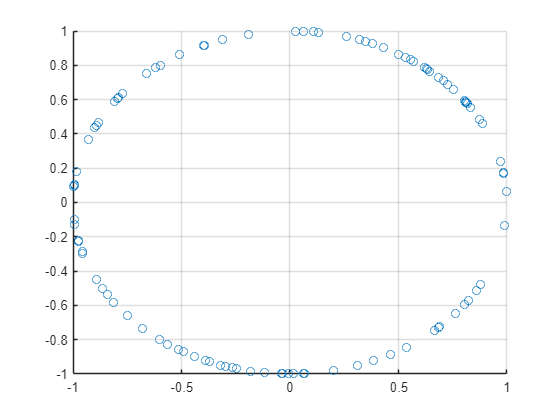

rng(123)
[x, y] = circlepoints(100);
scatter(x, y)
grid on

**Calling with one output**

This currently returns only the x values, but you will fix it.

M = circlepoints(100)

M =     0.9224   -0.3863
    0.9268    0.3756
   -0.9694    0.2455
    0.3499   -0.9368
    0.9866    0.1630
   -0.9531    0.3027
    0.8998   -0.4364
    0.1112   -0.9938
   -0.9694   -0.2454
    0.6337    0.7736


# Get random points on the unit circle

`n` is the number of points

`[x,y]` are the x and y values of the points.  If only one output is requested, it is a 2-column matrix with the x and y values in the first and second columns respectively.

## Examples

`[x,y] = circlepoints(n)`

`M = circlepoints(n)`

The function `circlepoints` returns `n` random (x,y) points on the unit circle.

function [x, y] = circlepoints(n)
    % Generate random points
    x = randn(n, 2);
    % Normalize to lie on the circle
    x = x./vecnorm(x, 2, 2);
    
    % TASK 1:
    % ENTER TASK 1 CODE HERE:
    if nargout > 1
        
        % Split into x and y components
        y = x(:, 2);
        x = x(:, 1);
    end
end